# Exploring unreported cases

## Load Data

clear;
%load_data_county;
%load_data_us;
load_data_global;
data_4_s1 = [data_4(:, 1) cumsum(movmean(diff(data_4')', 7, 2), 2)];
popu_orig = popu;
countries_orig = countries;

## Filter data to select regions

Here we choose, which regions we are interested in. Regions that do not show a stable pattern (for example, Washington) should not be chosen

sel_idx = popu < -1;
% sel_idx = startsWith(countries_orig, 'Los Angeles') | startsWith(countries_orig, 'New York City');
% sel_idx = startsWith(countries_orig, 'California')| startsWith(countries_orig, 'New York') | startsWith(countries_orig, 'Texas') | startsWith(countries_orig, 'Washington');
% sel_idx = sel_idx | startsWith(countries_orig, 'New Jersey')| startsWith(countries_orig, 'Illinois') | startsWith(countries_orig, 'Massachusetts');
% sel_idx = strcmpi(countries_orig, 'Massachusetts'); 
% sel_idx = find((data_4(:, 75)>10000));
sel_idx = startsWith(countries, 'US');
data_4_s = data_4_s1(sel_idx, :);
popu = popu_orig(sel_idx);
countries = countries_orig(sel_idx);


## Prepare training

%sd_start = T_tr
start_time = 140;
end_time = 182;
T_tr = start_time;
T_val = end_time - T_tr;

horizon = 100;

alpha = 1; %best_param_list_no(j, 3)*0.1;
k = 1; %best_param_list_no(j, 1);
jp = 7; %best_param_list_no(j, 2);


## Plot a region's data

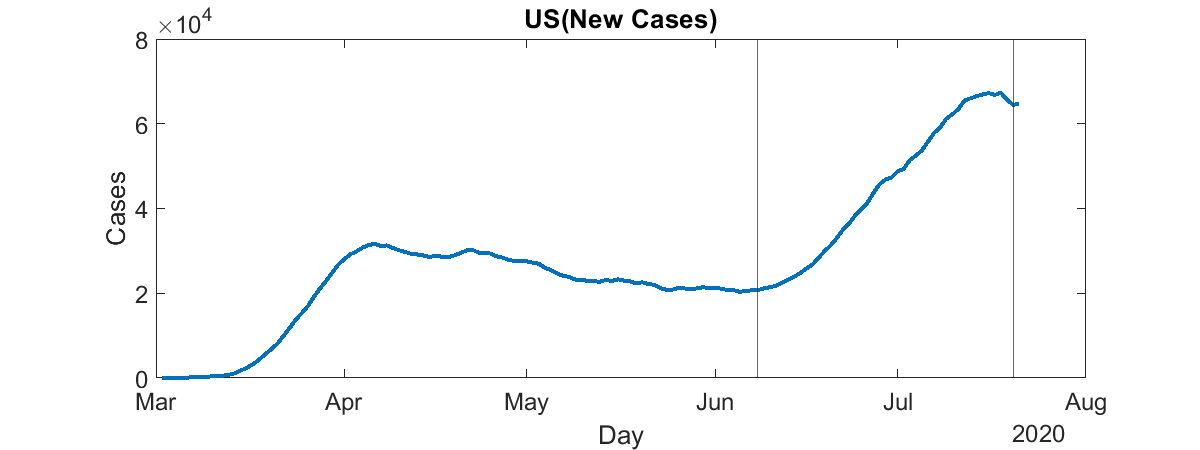

sel_reg = "US"; % Select a region to predict

 

xx = find(strcmpi(countries, sel_reg));
if isempty(xx)
    cid = 1; % Default to the first region in the list
else
    cid = xx;
end

figure('DefaultAxesFontSize',18);
offset = 40;
trueshow = (offset:size(data_4_s, 2));
Tx = datetime(2020, 1, 21)+ caldays(trueshow);
plot(Tx(2:end), diff(data_4_s(cid, offset:end)), 'LineWidth', 3); hold on;
xline(Tx(start_time-offset)); hold on; xline(Tx(end_time-offset)); hold off;

title([countries{cid} '(New Cases)'])
xlabel('Day');
ylabel('Cases');
set(gcf,'position',[10,10,1200,450])
%legend({'True', 'S', 'NL(i)', 'NL(f)', 'F'}, 'Location','northeast', 'Interpreter', 'latex');
hold off;

## Search for the best fixed point for FIR

first_val = 3;
checkvals = (first_val:(end_time-start_time-first_val));

min_pts = ones(length(sel_idx), 1);
data_4_s = data_4_s1(sel_idx, :);
popu = popu_orig(sel_idx);
countries = countries_orig(sel_idx);
a_T = data_4_s(:, end)./popu;
err_mat = Inf*ones(length(popu), (end_time-start_time-1));


for ii=checkvals(1):2:checkvals(end)
    [~, ~, err, ~, ~, this_del] = learn_un_fix_beta(data_4_s(:, start_time-k*jp:end_time), popu, k, jp, alpha, a_T, ii*ones(length(popu), 1), 'l', 0);
    val_idx =  this_del>0 & this_del< 1;
    err_mat(:, ii) = err;
end
[val, min_pts] = min(err_mat, [], 2);
min_pts(val > data_4_s(:, end)) = 0;



## Auto-detect using FIR and NLR

[beta_cell, un_prob_f, err, init_dat, ci_f, del, fittedC] = learn_un_fix_beta(data_4_s(:, start_time-k*jp:end_time), popu, k, jp, alpha, a_T, 5, 'l', 1);
infec_un0_f = var_simulate_pred_un(init_dat, 0, beta_cell, popu, k, horizon, jp, 1./un_prob_f);

data_4_s = data_4_s1(sel_idx, :);
popu = popu_orig(sel_idx);
countries = countries_orig(sel_idx);
[beta_auto_un1, un_prob_i, init_dat, fittedC, ci_i] = learn_nonlin(data_4_s(:, T_tr-k*jp:T_tr+T_val), popu, k, jp, 1, [], 'i');
infec_un0_i = var_simulate_pred_un(init_dat, 0, beta_auto_un1, popu, k, horizon, jp, 1./un_prob_i);

[beta_auto_un2, un_prob_ll, init_dat, fittedC, ci_ll] = learn_nonlin(data_4_s(:, T_tr-k*jp:T_tr+T_val), popu, k, jp, 1, [], 'i');
infec_un0_ll = var_simulate_pred_un(init_dat, 0, beta_auto_un2, popu, k, horizon, jp, 1./un_prob_ll);

## Generate table for unreported cases

We have assumed that the dynamics don't change in the time period under consideration.  We do not provide any tests to confirm this. For now, this has to be assessed visually.

ci_f = ci_f(:);
delim = ' & ';
endline = '\\';
res_i = {}; res_ll = {}; res_f = {};
for j=1:length(popu)
    if del(j)>1 || del(j)< 0
        res_f{j} = 'FAILED';
    else
        res_f{j} = [num2str(1./(ci_f{j}(1, 2))),' - ' , num2str(1./(un_prob_f(j))),' - ', num2str(1./((1-del(j))*ci_f{j}(1, 1)))];   
    end
    
    res_i{j} =  [num2str(1./(ci_i{j}(1, 2))),' - ' , num2str(1./(un_prob_i(j))),' - ',  num2str(1./(ci_i{j}(1, 1)))];   
    res_ll{j} = [num2str(1./(ci_ll{j}(1, 2))),' - ' , num2str(1./(un_prob_ll(j))),' - ', num2str(1./(ci_ll{j}(1, 1)))];   
    
    disp([countries{j}, delim, res_i{j}, delim, res_ll{j}, delim res_f{j}, endline]);   
end

US & 22.8088 - 25.8122 - 29.7265 & 22.8088 - 25.8122 - 29.7265 & FAILED\\


## Plot comparison for selected region

figure('DefaultAxesFontSize',18);
sel_reg = "US"; % Select a region to predict

 

xx = find(strcmpi(countries, sel_reg));
if isempty(xx)
    cid = 1; % Default to the first region in the list
else
    cid = xx;
end

%T_tr = Final_list{cid, 1};
T_tr = start_time;
offset = 50;
trueshow = (offset:size(data_4_s, 2));
Tx = datetime(2020, 1, 21)+ caldays(trueshow);
plot(Tx(2:end), diff(data_4_s1(cid, offset:end)), 'LineWidth', 3);
hold on;

Tx = datetime(2020, 1, 21)+caldays(start_time+1:start_time+size(infec_un0_f, 2));
%Tx_sd = datetime(2020, 1, 21)+caldays(sd_start+1:sd_start+size(infec_un0_i, 2));

%yy = diff(infec_un(cid, :)); plot(Tx(2:5:end), yy(1:5:end), 'g', 'Marker', 'o', 'LineWidth', 2, 'MarkerSize', 10); hold on;
yy = diff(infec_un0_i(cid, :)); plot(Tx(2:5:end), yy(1:5:end), 'r', 'Marker', '+', 'LineWidth', 2, 'MarkerSize', 10, 'LineStyle', '-'); hold on;
yy = diff(infec_un0_ll(cid, :)); plot(Tx(2:5:end), yy(1:5:end), 'r', 'Marker', 'x', 'LineWidth', 2, 'MarkerSize', 10); hold on;
yy = diff(infec_un0_f(cid, :)); plot(Tx(2:5:end), yy(1:5:end), 'g', 'Marker', 'o', 'LineWidth', 2, 'MarkerSize', 10); hold on;

title([countries{cid} '(New Cases)'])
xlabel('Day');
ylabel('Cases');
legend({'True', 'NL(i)', 'NL(f)', 'F'}, 'Location','northeast', 'Interpreter', 'latex');
hold off;

## Generate plots for all regions

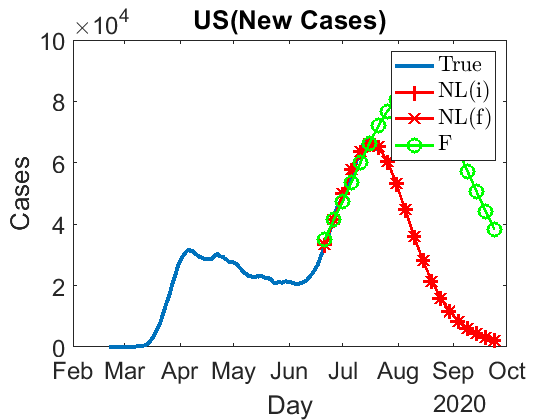


for cid = 1: length(countries)
    %subplot(length(countries), 1, cid);
    figure('DefaultAxesFontSize',18);
    
    offset = 30;
    trueshow = (offset:size(data_4_s, 2));
    Tx = datetime(2020, 1, 21)+ caldays(trueshow);
    plot(Tx(2:end), diff(data_4_s(cid, offset:end)), 'LineWidth', 3);
    hold on;
    
    Tx = datetime(2020, 1, 21)+caldays(T_tr+1:T_tr+size(infec_un0_i, 2));
    Tx_sd = datetime(2020, 1, 21)+caldays(start_time+1:start_time+size(infec_un0_i, 2));
    
%    yy = diff(infec_un(cid, :)); plot(Tx(2:5:end), yy(1:5:end), 'g', 'Marker', 'o', 'LineWidth', 2, 'MarkerSize', 10); hold on;
    yy = diff(infec_un0_i(cid, :)); plot(Tx(2:5:end), yy(1:5:end), 'r', 'Marker', '+', 'LineWidth', 2, 'MarkerSize', 10, 'LineStyle', '-'); hold on;
    yy = diff(infec_un0_ll(cid, :)); plot(Tx(2:5:end), yy(1:5:end), 'r', 'Marker', 'x', 'LineWidth', 2, 'MarkerSize', 10); hold on;
    yy = diff(infec_un0_f(cid, :)); plot(Tx(2:5:end), yy(1:5:end), 'g', 'Marker', 'o', 'LineWidth', 2, 'MarkerSize', 10); hold on;
    
    title([countries{cid} '(New Cases)'])
    xlabel('Day');
    ylabel('Cases');
    legend({'True', 'NL(i)', 'NL(f)', 'F'}, 'Location','northeast', 'Interpreter', 'latex');
    hold off;
    
end